# Radar

**Overview**

The `Radar` chart compares two line plots of cyclic data arranged around a circular (polar) axes. The chart data comprises:

- `AngularData` - an increasing numeric vector representing the independent variable.

- `RadialData` - a two-column matrix of data, each column of which is plotted against the `AngularData` around the circle.

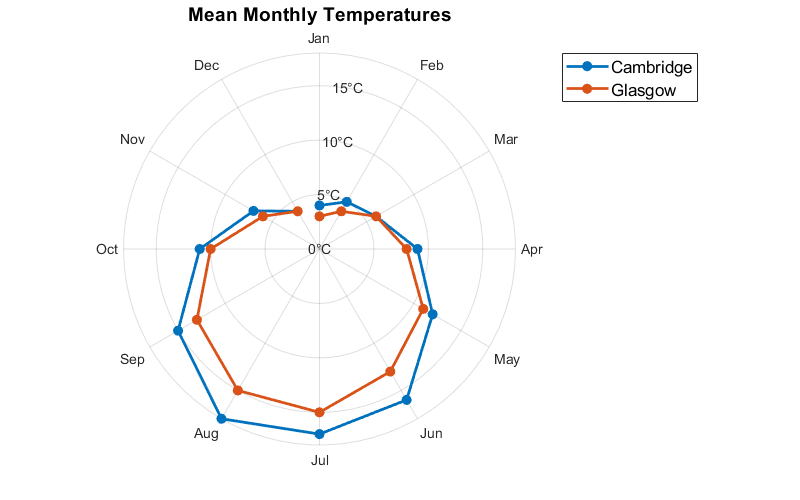

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'Radar.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'Radar'))) the source code for the `Radar` chart.

Documentation for [polaraxes](matlab: web(fullfile(matlabroot, 'help', 'matlab', 'ref', 'polaraxes.html'), '-helpbrowser')) and [polarplot](matlab: web(fullfile(matlabroot, 'help', 'matlab', 'ref', 'polarplot.html'), '-helpbrowser')).

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.Radar

## Create sample chart data.

The angular data comprises the months of the year, and the radial data are the average monthly temperatures for two locations (Cambridge and Glasgow).

months = 1 : 12;
meanMonthlyTemps = [4, 5, 6, 9, 12, 16, 17, 18, 15, 11, 7, 4
         3, 4, 6, 8, 11, 13, 15, 15, 13, 10, 6, 4].';

## Create a figure for the chart.

f = galleryFigure( 'Name', 'Radar Example' );

## Create the chart, specifying the parent and input data.

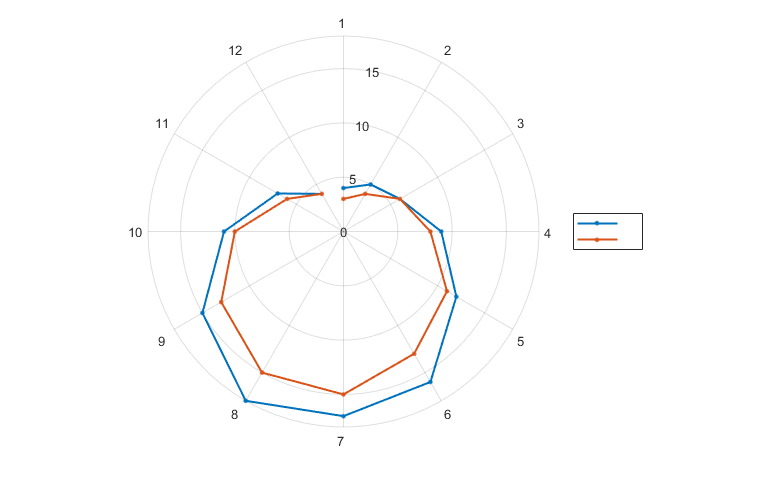

R = Radar( 'Parent', f, ...
           'AngularData', months, ...
           'RadialData', meanMonthlyTemps );

## Annotate the chart.

Create and format the title.

R.Title.String = 'Mean Monthly Temperatures';
R.Title.FontSize = 14;

Define and customize the legend entries.

R.LegendText = {'Cambridge', 'Glasgow'};
R.LegendFontSize = 12;
R.LegendLocation = 'northeastoutside';

Customize the angular tick labels.

monthNames = month( datetime( 2000, 1:12, 1 ), 'shortname' );
R.AngularTickLabel = monthNames;

Customize the radial tick labels.

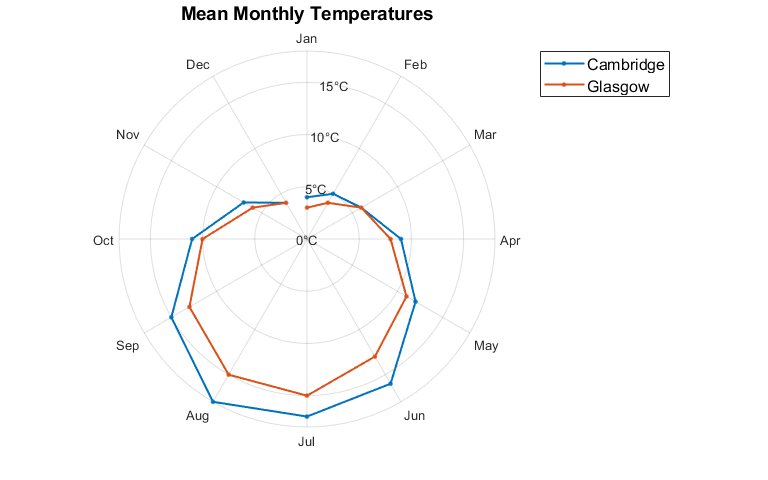

R.RadialTickLabel = strcat( R.RadialTickLabel, [char( 176 ), 'C'] );

## Customize the chart appearance.

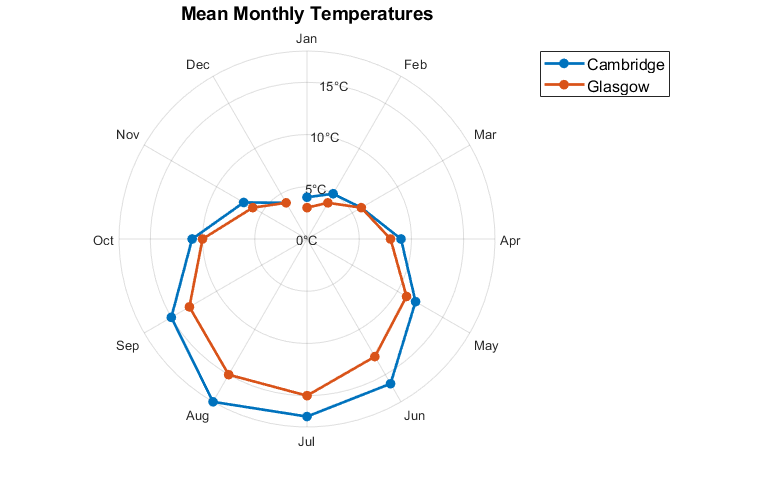

R.MarkerSize = 25;
R.LineWidth = 2;

## Change the underlying chart data.

First, compute the mean temperature in each quarter.

meanQuarterlyTemps = mean( reshape( meanMonthlyTemps, 3, [] ) );
meanQuarterlyTemps = reshape( meanQuarterlyTemps, [], 2 );

Update the angular data.

R.AngularData = 1 : 4;

Update the radial data.

R.RadialData = meanQuarterlyTemps;

Update the annotations.

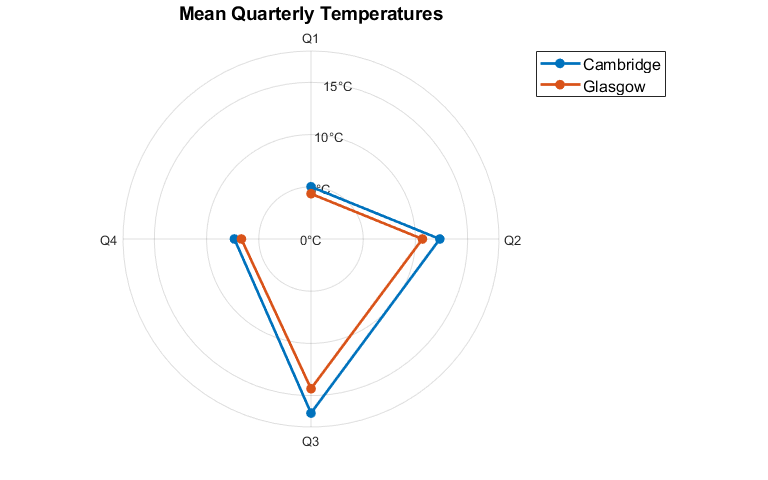

R.Title.String = 'Mean Quarterly Temperatures';
R.AngularTickLabel = {'Q1', 'Q2', 'Q3', 'Q4'};